# MEDA script for the Selwood data 

**MEDA Version:** v1.6

**Coded by:** José Camacho (josecamacho@ugr.es) and Jesús García (gsus@ugr.es)

**Last modification:** 23/Jan/2025

## Description 

Multivariate exploratory data analysis (MEDA) of the Selwood data: The objective of this experiment is to illustrate that the MEDA framework can be used to understand the data and as a valid means to perform non-automated variable selection.

Data set:

The data set was downloaded from http://michem.disat.unimib.it/chm/download/datasets.htm. It consists of 31 antifilarial antimycin A1 analogues for which 53 physicochemical descriptors were calculated for Quantitative Structure-Activity Relationship (QSAR) modelling. The set of descriptors is 

listed below:

Indices Descriptors

1:10 	ATCH1 ATCH2 ATCH3 ATCH4 ATCH5 ATCH6 ATCH7 ATCH8 ATCH9 ATCH10

11:20 	DIPV_X DIPV_Y DIPV_Z DIPMOM ESDL1 ESDL2 ESDL3 ESDL4 ESDL5 ESDL6

21:30 	ESDL7 ESDL8 ESDL9 ESDL10 NSDL1 NSDL2 NSDL3 NSDL4 NSDL5 NSDL6

31:40 	NSDL7 NSDL8 NSDL9 NSDL10 VDWVOL SURF_A MOFI_X MOFI_Y MOFI_Z PEAX_X

41:50 	PEAX_Y PEAX_Z MOL_WT S8_1DX S8_1DY S8_1DZ S8_1CX S8_1CY S8_1CZ LOGP

51:53 	M_PNT SUM_F SUM_R	

These descriptors are used for predicting in vitro antifilarial activity

(-LOGEC50). This data set has been employed for testing variable selection methods.

## Inicialization, remember to set the path of the toolbox

load selwood

prep_x = 2; % auto-scale X
prep_y = 2; % auto-scale Y
max_LVs = 20; % maximum number of PCs to take into account

y = x(:,end);
xn = x(:,1:end-1);

## Step 1: Selection of the LVs

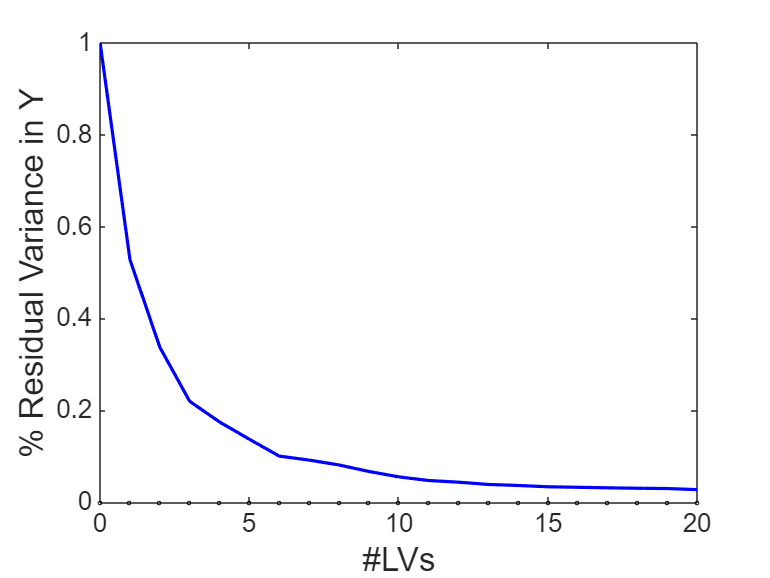

varPls(xn,y,'LVs',0:max_LVs,'PreprocessingX',prep_x,'PreprocessingY',prep_y); % 3 or 6 LVs

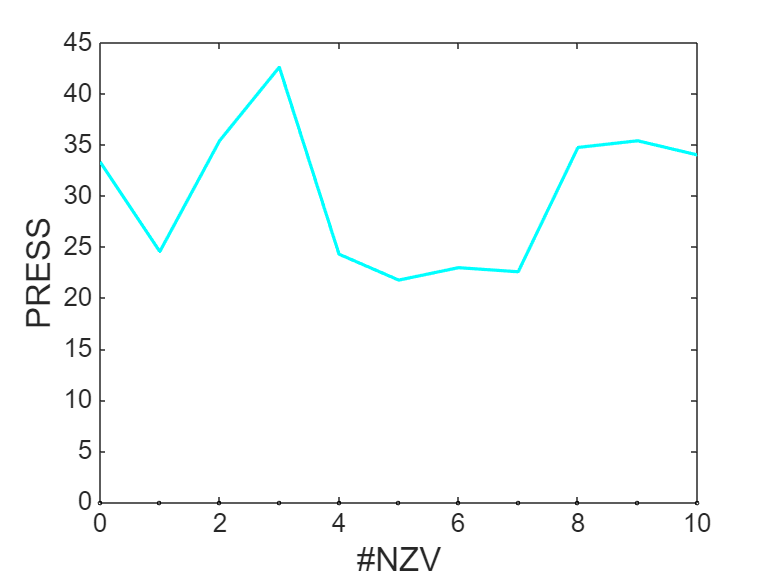

cumpress=crossvalPls(xn,y,'LVs',0:10); % LVs 2 and 3 are not predictive

## Step 2: Observations distribution and relationships

Scores and residuals, outliers detection.

5 LVs are used for visualization

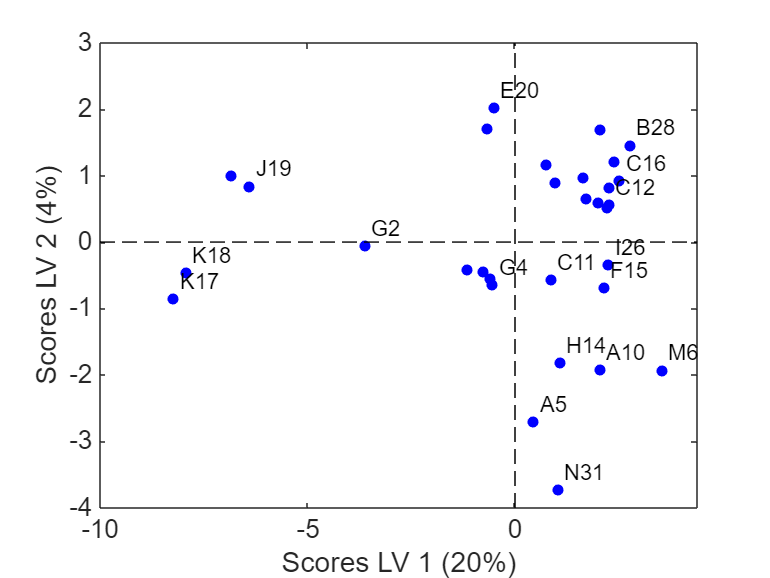

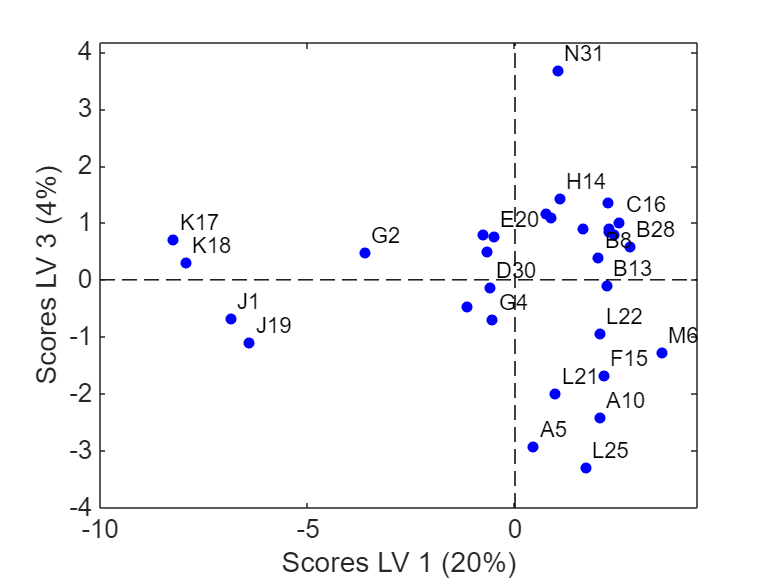

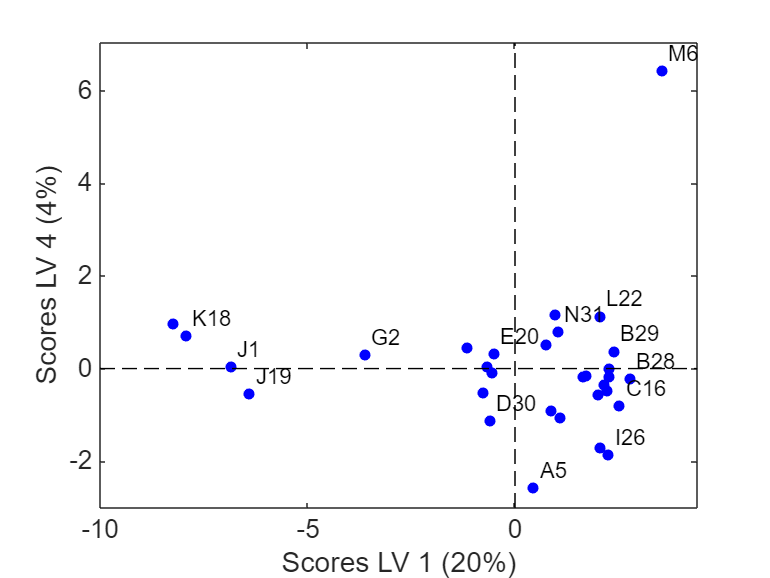

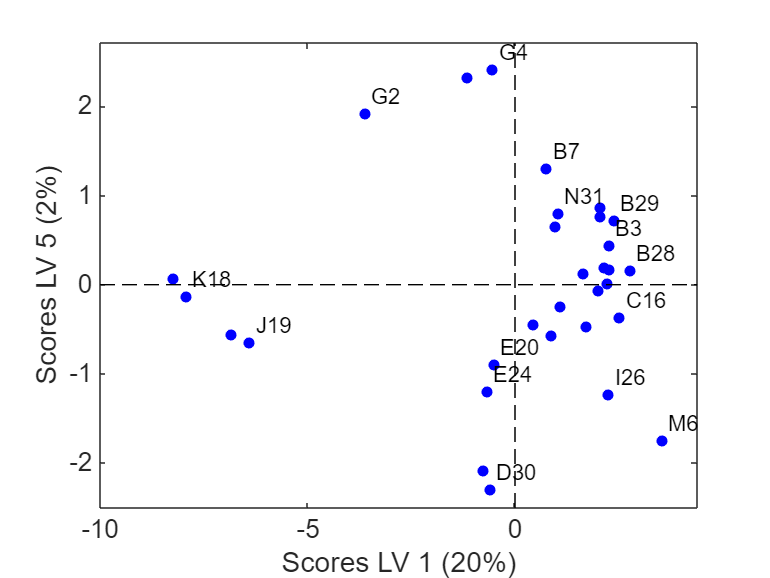

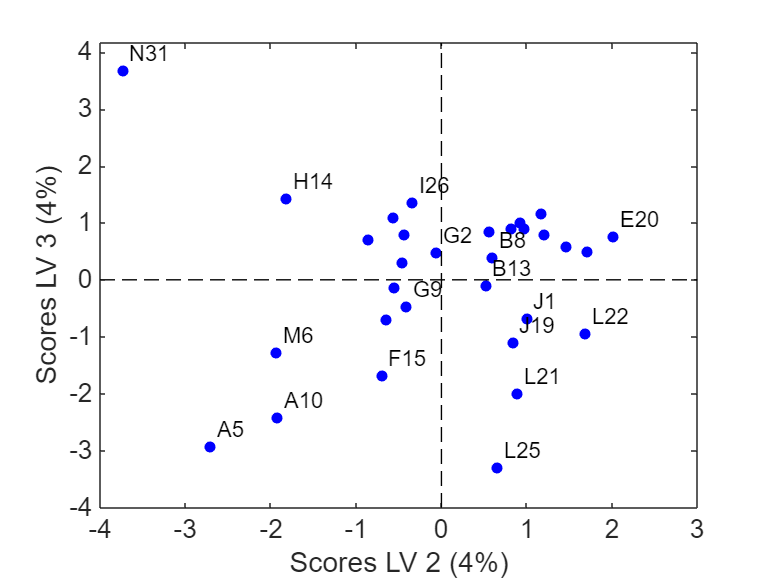

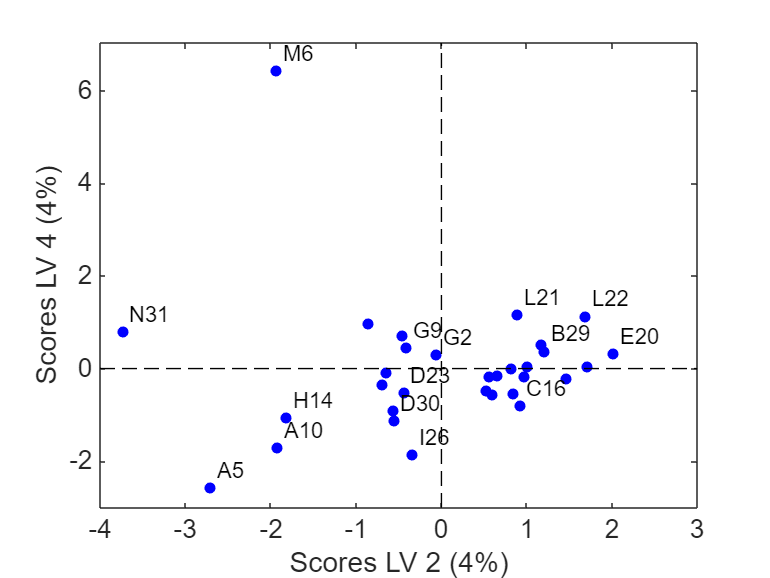

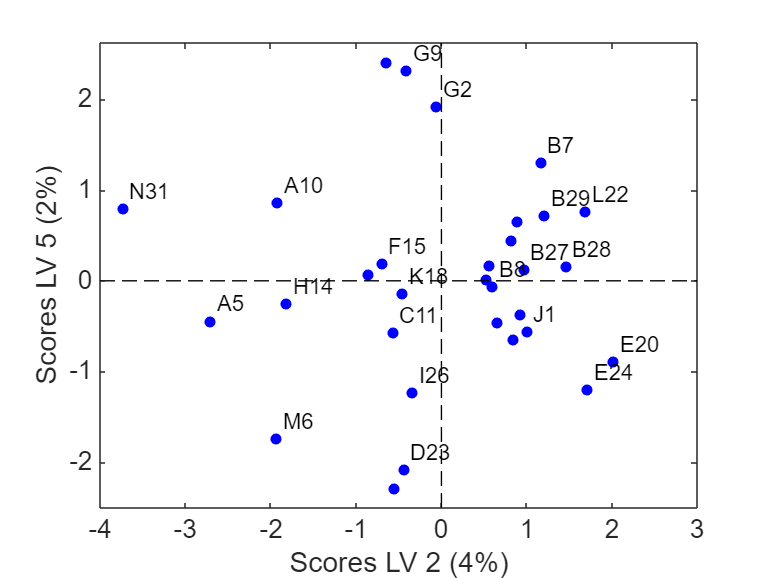

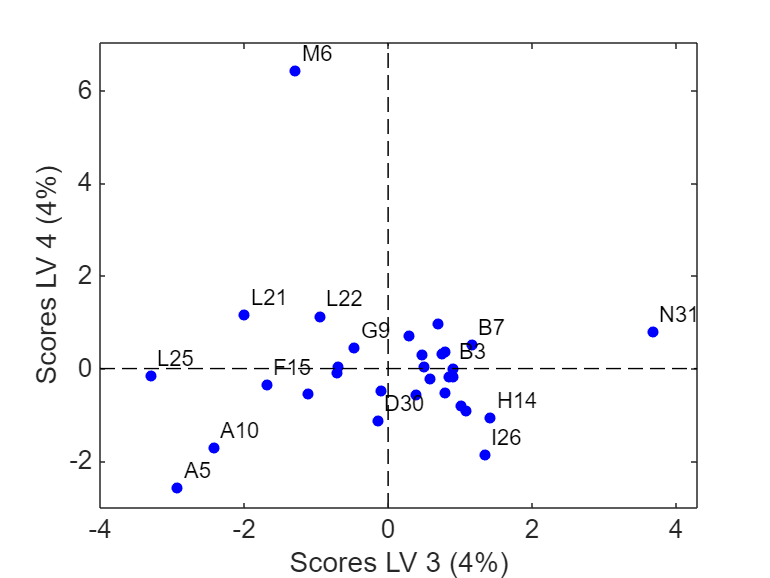

T = scoresPls(xn,y,'LVs',1:5,'ObsTest',[],'PreprocessingX',prep_x,'PreprocessingY',prep_y,'PlotType','Scatter','ObsLabel',Obs); 

Four abnormal observations are found in LV1 (J1(5), J19(3), K18(6), K17(1)) which should be studied with more detail. Also, N31(16) is an outlier in LV2 vs LV3, and M6(18) in LV4.

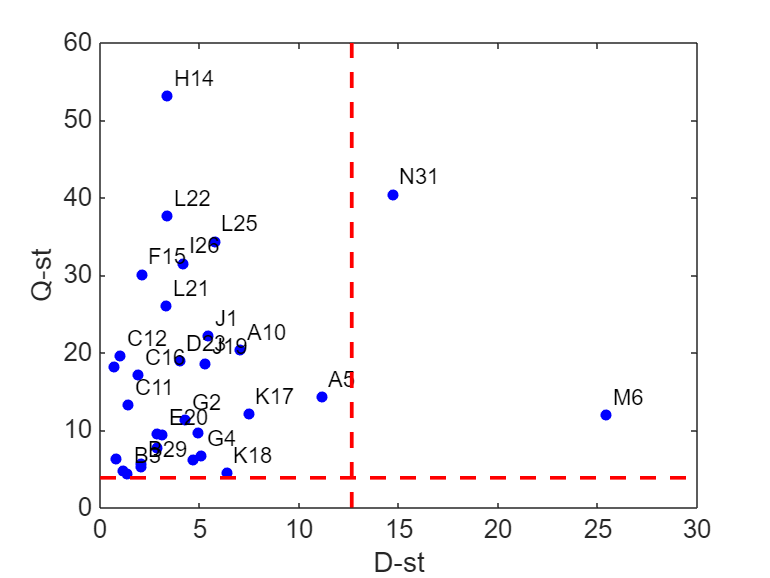

mspcPls(xn,y,'LVs',1:5,'ObsTest',[],'PreprocessingX',prep_x,'PreprocessingY',prep_y,'PlotType','Scatter','ObsLabel',Obs); 

M6(18) is the clearest outlier in the D-st. No high residual (Q-st) are found.

## Step 3: Investigate differences between observations

Apply oMEDA to outliers found

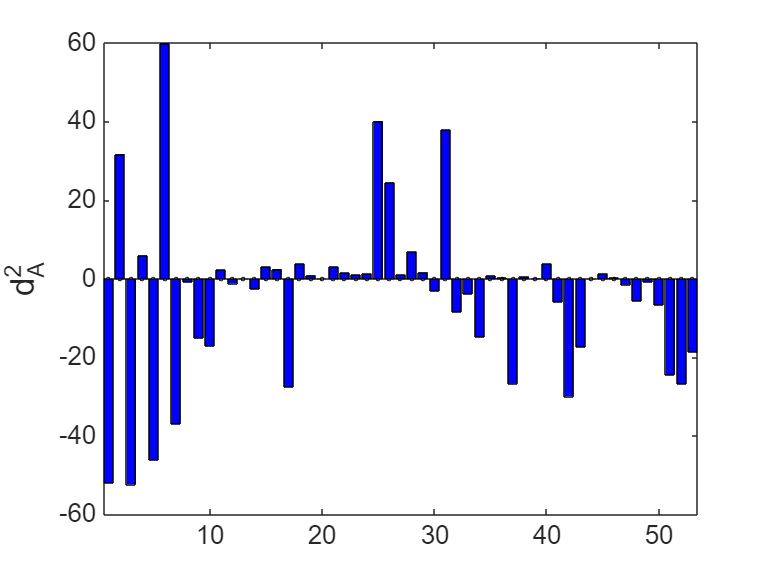

dummy=-ones(31,1);
dummy([1,3,5,6])=1;
omedaPls(xn,y,1,xn,dummy,'PreprocessingX',prep_x,'PreprocessingY',prep_y);

The abnormal observations present a generalized higher magnitude value than common observations (in both positive and negative directions)

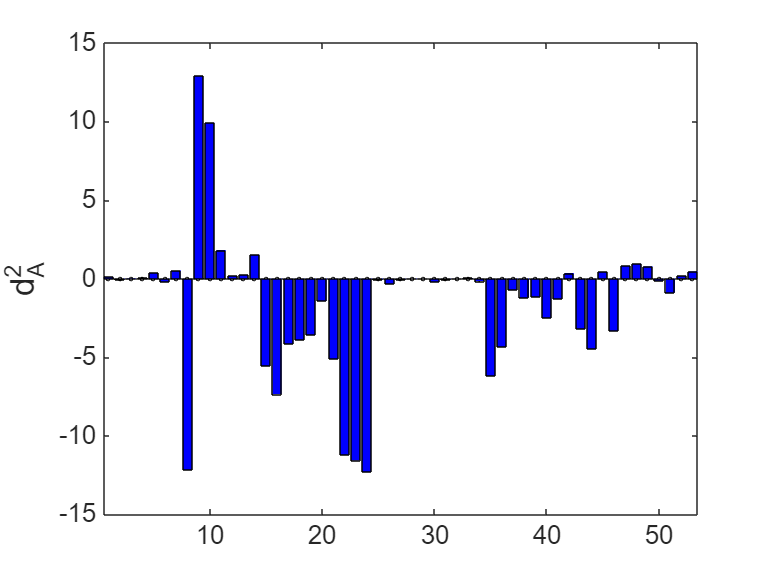

dummy=-ones(31,1);
dummy(16)=1;
omedaPls(xn,y,2:3,xn,dummy,'PreprocessingX',prep_x,'PreprocessingY',prep_y);

The deviation of N31(16) is mainly related to an anomalous value of ATCH8-ATCH10 

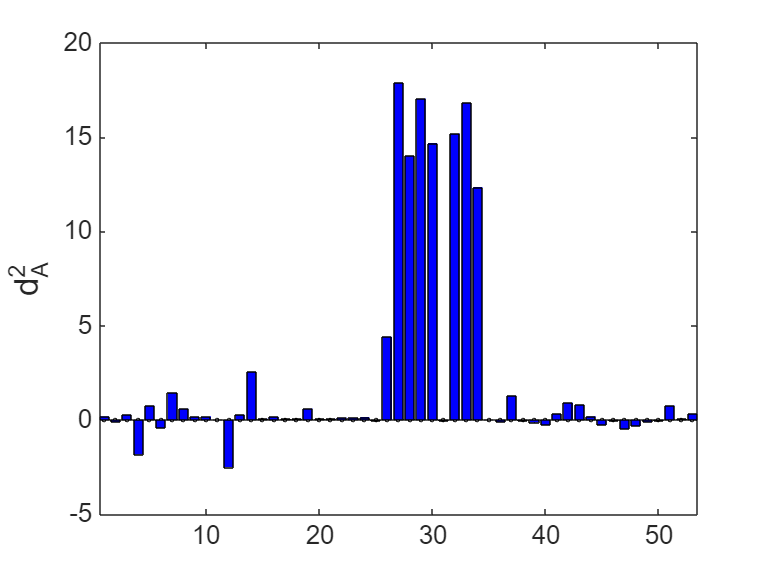

dummy=-ones(31,1);
dummy(18)=1;
omedaPls(xn,y,4,xn,dummy,'PreprocessingX',prep_x,'PreprocessingY',prep_y);

the anomalour residual in M6(18) is related to a generalized high value in most of NSDL variables

## Step 4: Variables distribution and relationships

Loadings, MEDA and residuals

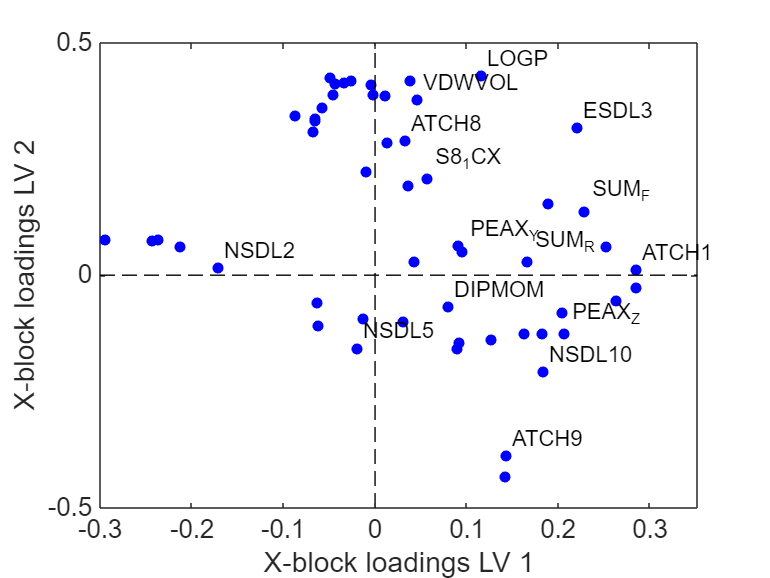

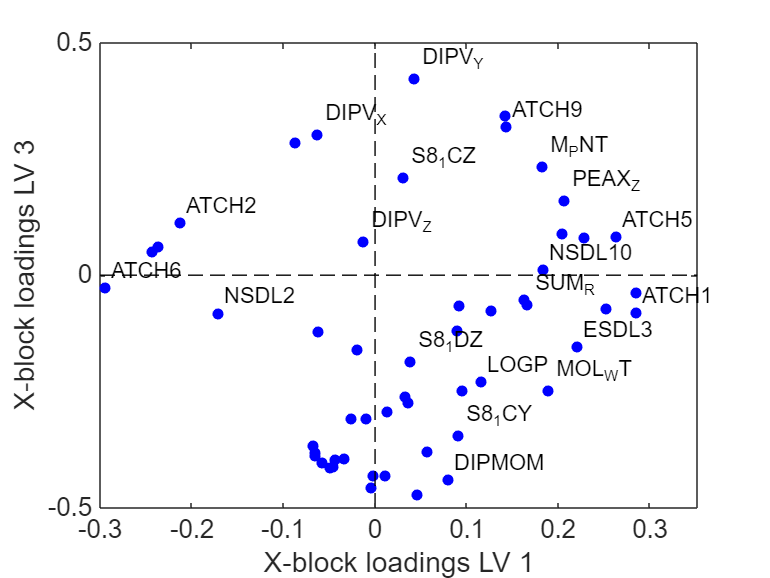

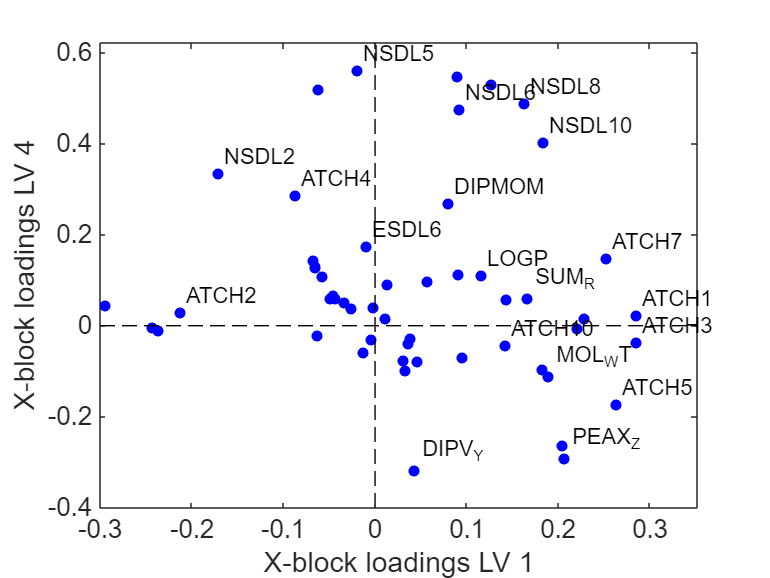

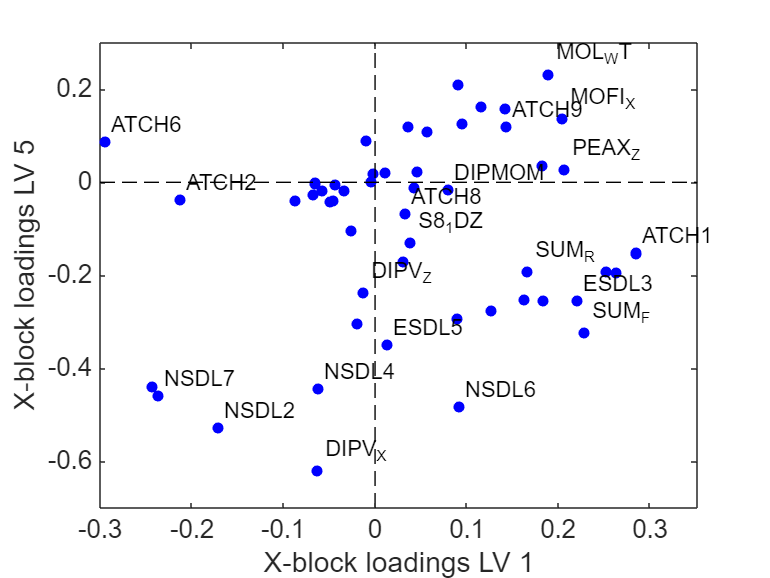

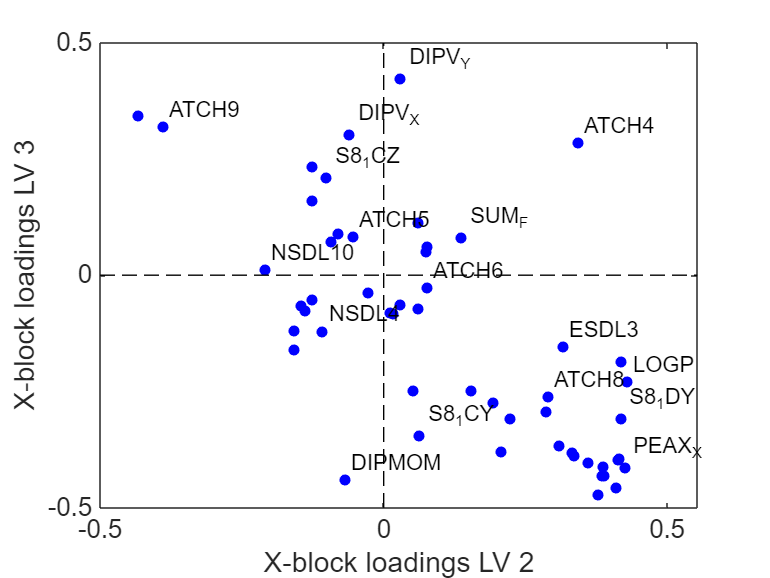

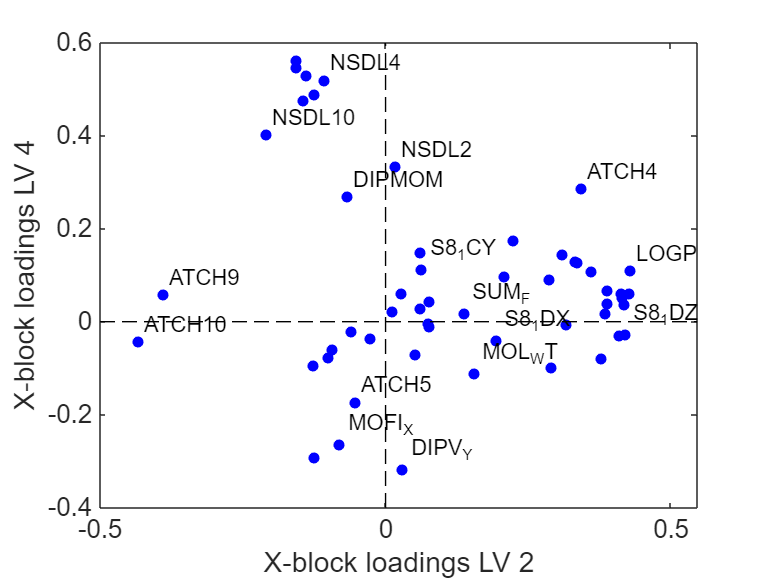

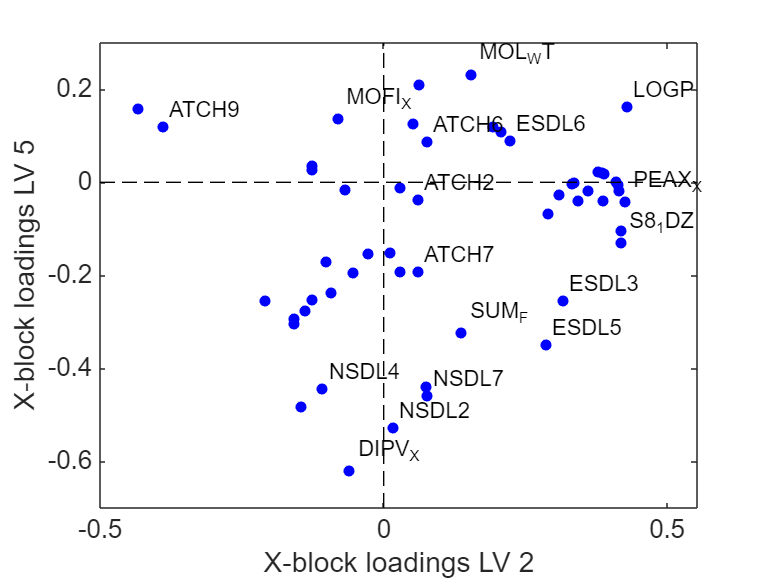

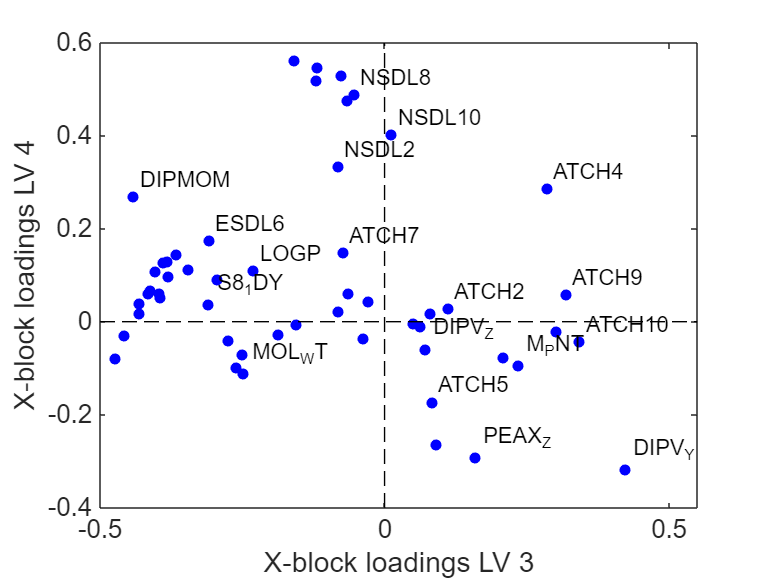

P = loadingsPls(xn,y,'LVs',1:5,'PreprocessingX',prep_x,'PreprocessingY',prep_y,'VarsLabel',Vars);

A main limitation of loading plots is that only two LVs are assessed at a time. Also, although some correlations are found (e.g ATCH9 and ATCH10), it is hard to interpret

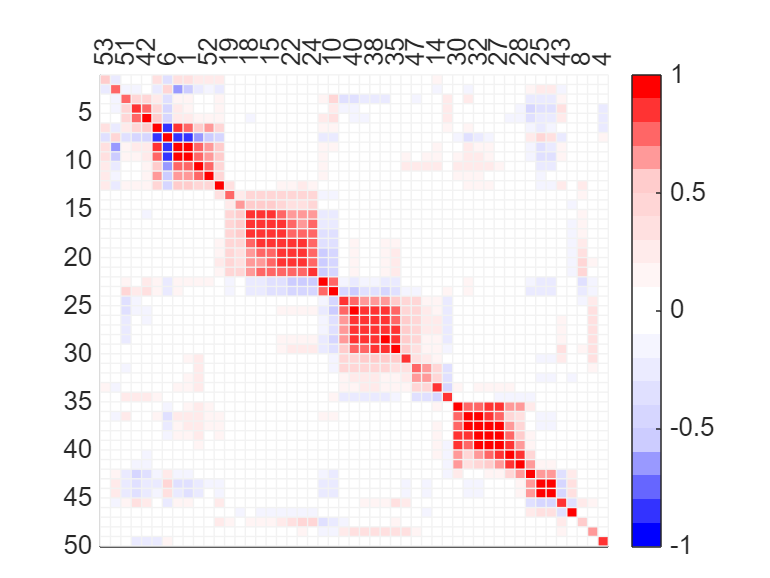

meda_res = medaPls(xn,y,'LVs',1:5,'PreprocessingX',prep_x,'PreprocessingY',prep_y,...
'Threshold',0.5,'Seriated', true, 'Discard', true);

With MEDA, the contribution of the selected LVs can be observed at once. Also, the groups of variables are easily found. There are several groups of related variables, which cannot be observed in the loading plots, but it is not clear which are the most predictive. Here we can use a simple trick (Step 3b): join xn and y in a single block and perform PCA and MEDA. 

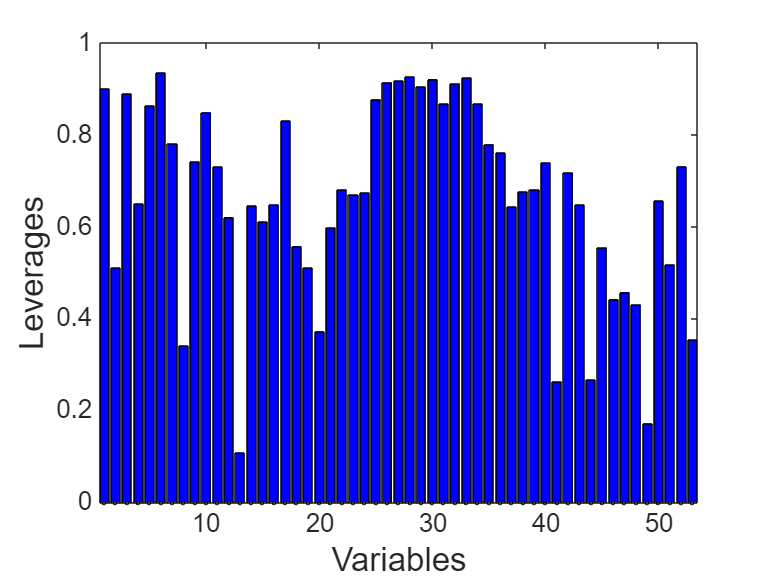

leveragesPls(xn,y,'LVs',1:5,'PreprocessingX',prep_x,'PreprocessingY',prep_y,'VarsLabel',Vars); 

ATCH4, DIPV_X and LOGP variables with the higest leverage on the model

## Step 4b: Variables distribution and relationships in PCA join xn and y

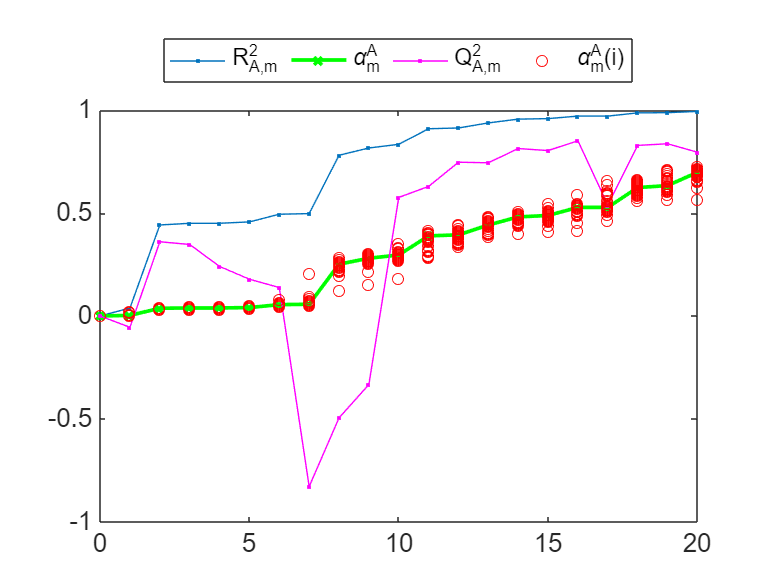

Vars2 = {Vars{:} '-LOGEC50'};
xaug = [xn y];

SVIplot(xaug,'PCs',1:max_LVs,'Vars',size(xaug,2),'Groups',size(xaug,1),'Preprocessing',prep_x); 

The SVI plot is useful to determine the number of PCs when a single variable is of interest. 2 PCs may be a good choice (low uncertainty of alpha parameters while Q2 remains high)

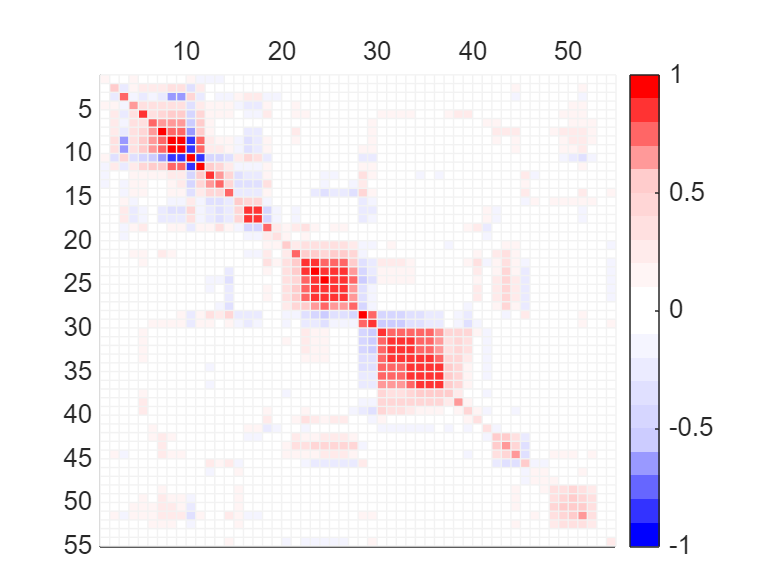

[meda_res,map,ord] = medaPca(xaug,'PCs',1:2,'Preprocessing',prep_x,'Threshold',0.5,'Seriated',1);

It may be useful to combine this plot with the one focused on the column representing -LOGEC50 (variable 54)

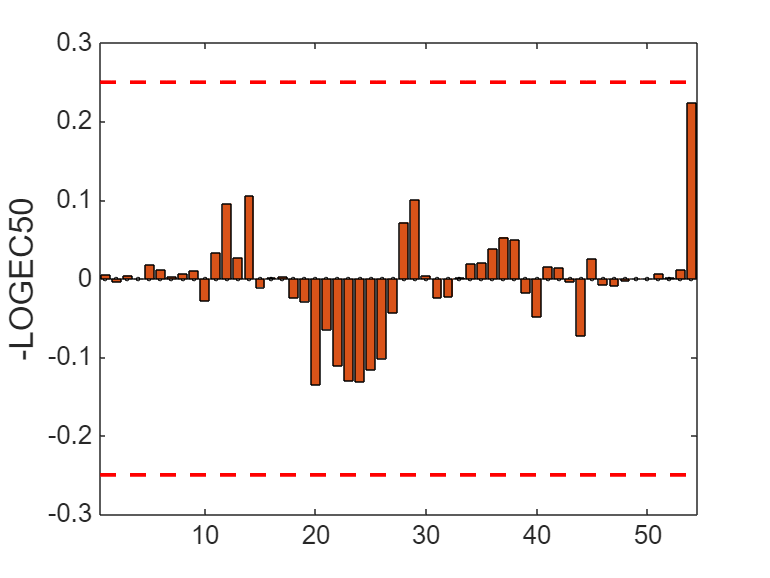

plotVec(meda_res(:,54),'EleLabel',1:54,'XYLabel',{[],'-LOGEC50'},'LimCont',[0.25, -0.25]);

Variables highlighted are 'ATCH1', 'ATCH3', 'ATCH5', 'ATCH7', 'ESDL3', 'SUM_F', 'ATCH6', 'NSDL1'

## Copyright (C) 2025  University of Granada, Granada

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program.  If not, see <http://www.gnu.org/licenses/>.